Author: **Arjan Gupta**

Due: March 27, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

# Forward Dyanamics of Three Link Manipuator

clear; clc; close all;

## Build Robot

### Create Rigid Body Elements

First, let us create a `rigidBodyTree` robot model. Then, we create the 3 rectangular arms of the robot.

robot = rigidBodyTree("DataFormat","column");
base = robot.Base;
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");

### Attach Joints

We specify the joints as revolute and set them to rotate around the z-axis.

jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt3 = rigidBodyJoint("jnt3","revolute");
jnt1.JointAxis = [0 0 1];
jnt2.JointAxis = [0 0 1];
jnt3.JointAxis = [0 0 1];

In the prompt of this assignment, we are given the following DH table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 0 			& 0	& 0	& \theta_1			\cr
2			& L_1 		& 0		& 0	& \theta_2		\cr
3			& L_2 			& 0			& 0 & \theta_3	\cr
}$$


% Link lengths
L1 = 4.0;
L2 = 3.0;
L3 = 2.0;
% Joint variables
theta1 = 0;
theta2 = 0;
theta3 = 0;
% DH table
dhparams = [0 0  0 theta1;
            L1 0 0 theta2;
            L2 0 0 theta3];
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');

### Set Physical Properties

% Masses (in kgs), given in assignment prompt
m1 = 20;
m2 = 15;
m3 = 10;
% Moments of inertia (in kgm^2), given in assignment prompt
I1 = 0.5;
I2 = 0.2;
I3 = 0.1;
% Set the masses
arm1.Mass = m1;
arm2.Mass = m2;
arm3.Mass = m3;
% Set the centers of masses
arm1.CenterOfMass = [L1/2, 0.1, 0.1];
arm2.CenterOfMass = [L2/2, 0.1, 0.1];
arm3.CenterOfMass = [L3/2, 0.1, 0.1];
% Set the inertias
arm1.Inertia = [I1,I1,I1,0,0,0];
arm2.Inertia = [I2,I2,I2,0,0,0];
arm3.Inertia = [I3,I3,I3,0,0,0];

### Assemble Robot

To assemble the robot, we add each joint to the body, and then add the body to the tree.

bodies = {base,arm1,arm2,arm3};
joints = {[],jnt1,jnt2,jnt3};
for i = 2:length(bodies)
    bodies{i}.Joint = joints{i};
    addBody(robot,bodies{i},bodies{i-1}.Name)
end

## Problem 1

In this problem we implement the forward dynamics and plot the joint accelerations and velocities in response to actuator torques.

% Set gravity direction
robot.Gravity = [0; -9.81; 0];
% Set joint torques and velocities, as given in assignment prompt
jointTorqs = [20;5;1];
jointVelsInit = [0;0;0];
% Set initial position, as given in assignment prompt
initialPosition = [-pi/3;pi/2;pi/6];

We want to calculate the forward dynamics over a time period. Let us choose a time period of 10 seconds with 10 ms step.

First, we define a time array and time increment (step) size.

time_step = 0.045; % arbitrarily small time step
time_arr = 0:time_step:5;
[~,time_arr_len] = size(time_arr);

Now we can run a loop of calculations for the forward dynamics over this time.

% Declare 3D arrays to capture lists of acceleration, velocity, and
% position vectors
jointAccels = zeros(3,1,time_arr_len);
jointVels = zeros(3,1,time_arr_len+1);
jointVels(:,:,1) = jointVelsInit;
jointAngles = zeros(3,1,time_arr_len+1);
jointAngles(:,:,1) = initialPosition;
i = 1;
% Run the loop for forward dynamics
for t = time_arr
    jointAccels(:,:,i) = forwardDynamics(robot,jointAngles(:,:,i),jointVels(:,:,i),jointTorqs);
    jointVels(:,:,i+1) = jointAccels(:,:,i)*time_step;
    jointAngles(:,:,i+1) = jointAccels(:,:,i)*time_step*time_step;
    i = i + 1;
end
disp(jointAccels)


(:,:,1) =

 -396.3828
  394.4978
    2.3563


(:,:,2) =

 -543.4894
  541.5842
    1.3282


(:,:,3) =

 -360.5673
  358.6620
    1.3282


(:,:,4) =

 -580.9074
  579.0021
    1.3282


(:,:,5) =

 -307.8320
  305.9268
    1.3282


(:,:,6) =

 -630.1031
  628.1978
    1.3282


(:,:,7) =

 -235.5974
  233.6921
    1.3282


(:,:,8) =

 -685.1858
  683.2805
    1.3282


(:,:,9) =

 -151.6285
  149.7232
    1.3282


(:,:,10) =

 -729.9551
  728.0498
    1.3282


(:,:,11) =

  -81.6696
   79.7643
    1.3282


(:,:,12) =

 -750.5520
  748.6467
    1.3282


(:,:,13) =

  -49.1406
   47.2353
    1.3282


(:,:,14) =

 -754.8159
  752.9106
    1.3282


(:,:,15) =

  -42.3874
   40.4822
    1.3282


(:,:,16) =

 -755.2748
  753.3695
    1.3282


(:,:,17) =

  -41.6604
   39.7551
    1.3282


(:,:,18) =

 -755.3154
  753.4101
    1.3282


(:,:,19) =

  -41.5960
   39.6907
    1.3282


(:,:,20) =

 -755.3189
  753.4136
    1.3282


(:,:,21) =

  -41.5904
   39.6851
    1.3282


(:,:,22) =

 -755.319

disp(jointVels)


(:,:,1) =

     0
     0
     0


(:,:,2) =

  -17.8372
   17.7524
    0.1060


(:,:,3) =

  -24.4570
   24.3713
    0.0598


(:,:,4) =

  -16.2255
   16.1398
    0.0598


(:,:,5) =

  -26.1408
   26.0551
    0.0598


(:,:,6) =

  -13.8524
   13.7667
    0.0598


(:,:,7) =

  -28.3546
   28.2689
    0.0598


(:,:,8) =

  -10.6019
   10.5161
    0.0598


(:,:,9) =

  -30.8334
   30.7476
    0.0598


(:,:,10) =

   -6.8233
    6.7375
    0.0598


(:,:,11) =

  -32.8480
   32.7622
    0.0598


(:,:,12) =

   -3.6751
    3.5894
    0.0598


(:,:,13) =

  -33.7748
   33.6891
    0.0598


(:,:,14) =

   -2.2113
    2.1256
    0.0598


(:,:,15) =

  -33.9667
   33.8810
    0.0598


(:,:,16) =

   -1.9074
    1.8217
    0.0598


(:,:,17) =

  -33.9874
   33.9016
    0.0598


(:,:,18) =

   -1.8747
    1.7890
    0.0598


(:,:,19) =

  -33.9892
   33.9035
    0.0598


(:,:,20) =

   -1.8718
    1.7861
    0.0598


(:,:,21) =

  -33.9894
   33.9036
    0.0598


(:,:,22) =

   -1.8716
    1.7858

In order to plot the data, we flatten the arrays for acceleration and velocities into their own 2D arrays.

% Acceleration 2D arrays
accel_joint1 = reshape(jointAccels(1,1,:),[1,time_arr_len]);
accel_joint2 = reshape(jointAccels(2,1,:),[1,time_arr_len]);
accel_joint3 = reshape(jointAccels(3,1,:),[1,time_arr_len]);

% Velocity 2D arrays
vel_joint1 = reshape(jointVels(1,1,:),[1,time_arr_len+1]);
vel_joint2 = reshape(jointVels(2,1,:),[1,time_arr_len+1]);
vel_joint3 = reshape(jointVels(3,1,:),[1,time_arr_len+1]);

Now we come up with the acceleration and velocity evolution plots.

### Plot acceleration values against time

Let us now view our joint accelerations against time.

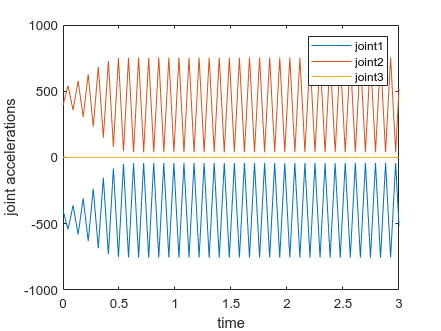

plot(time_arr, accel_joint1)
hold on
plot(time_arr, accel_joint2)
hold on
plot(time_arr, accel_joint3)
xlabel("time")
ylabel("joint accelerations")
xlim([0,3])
ylim([-1000,1000])
legend('joint1','joint2','joint3')
hold off

### Plot velocity values against time

Let us also plot the joint velcoities versus time.

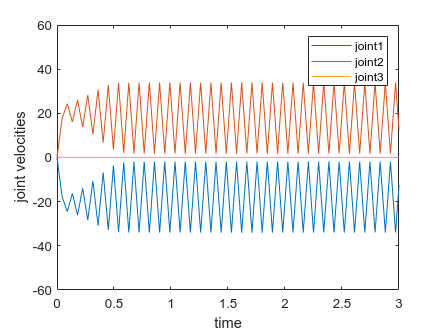

plot([time_arr 10.1], vel_joint1)
hold on
plot([time_arr 10.1], vel_joint2)
hold on
plot([time_arr 10.1], vel_joint3)
xlabel("time")
ylabel("joint velocities")
xlim([0,3])
ylim([-60,60])
legend('joint1','joint2','joint3')
hold off

## Problem 2